# **Big Question:**

## How do the factors of vaccination and death effect a disease?

We are asking this question to gain a better understanding of the SIRVD model. We aren't looking for a specific numerical answer, instead our aim is to interpret broad trends in our simulations. Seeing the direct effects of these variables can be used to inform disease response. In order to build our models we'll have to understand the math behind the SIRVD and SIRS models.

### **Research Matrix**

# **Methodology:**

The plan is as follows:

- Implement the SIRS model and the SIRVD model

- Perform parameter sweeps over vaccination rate and mortality rate

- Compare and interpret the data to see the effects of vaccination and death

# **Model:**

We will implement the SIRVD model and adapt it as the SIRS model. We have drawn a tenchi diagram that shows the boundry od the natural world:

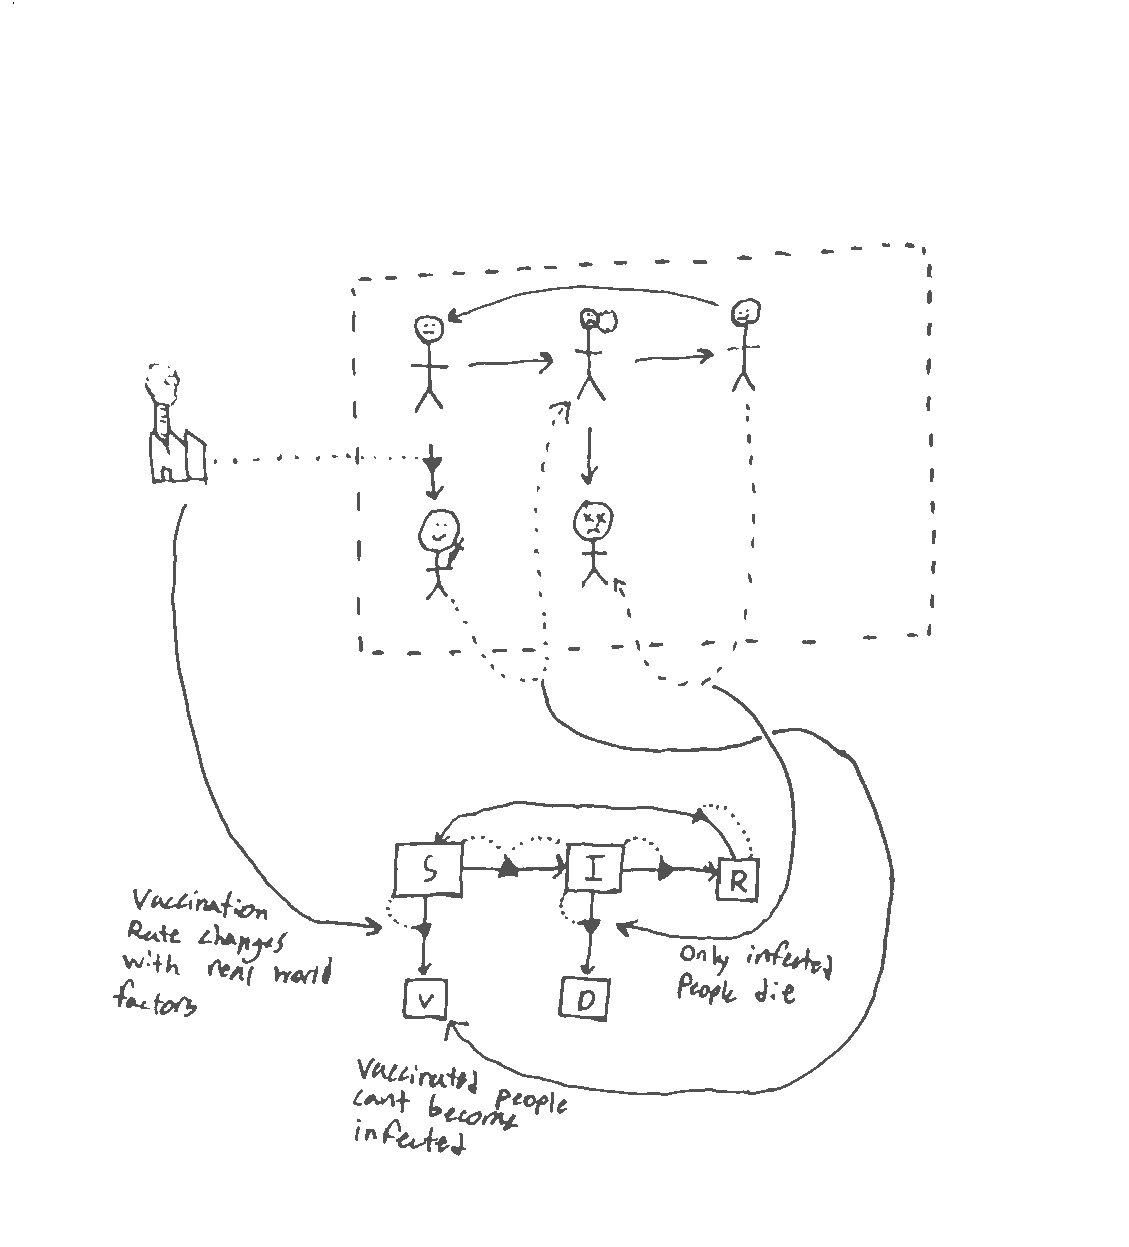

- S = Susceptible

- I = Infected

- R = Recovered

- V = Vaccinated

- D = Dead

With these stocks, we can establish the step functions


$$\begin{array}{l}
S_{n+1} =S_n +\alpha R-\beta \textrm{SI}-\sigma S\\
V_{n+1} =V_n +\sigma S\\
I_{n+1} =I_n +\beta \textrm{SI}-\gamma I\\
D_n =D_n +p\gamma I\\
R_n =R_n +\left(1-p\right)\gamma I-\alpha R
\end{array}$$


where:


$$\begin{array}{l}
\alpha =\textrm{resuseptible}\;\textrm{rate}\\
\beta =\textrm{infection}\;\textrm{rate}\\
\gamma =\textrm{rate}\;\textrm{of}\;\textrm{people}\;\textrm{exiting}\;\textrm{the}\;\textrm{infected}\;\textrm{state}\\
p=\textrm{mortality}\;\textrm{rate}\\
\sigma =\textrm{vaccination}\;\textrm{rate}
\end{array}$$


As noted in the diagram, our model is subject to certain limitations and assumptions:

- Only infected people die. In the real world all groups have an additional miniscule chance of dying at all times. The parameters typically used for this chance are extremely small (<2x10^-5) and given this parameter will not be a factor in either the SIRVD or SIRS model it can safely be disregarded

- Vaccinated people can't become infected. In reality vaccine effectiveness can differ between people and wear off. While this may make our models less useful for looking at raw number statistics, the effect that vacines have will remain the same in principle

- Vaccine rate only changes based on the number of susceptible people. There are many external factors in the real world that can contribute to vaccination rates. These include funding for programs, development time, and manufacturability. While this could be useful information, it's not necessary to see the effects of vaccination in general.

## **Implementation of the SIRS model**

First lets take a look at the SIRS model. This is a model primarily used for modeling infectious diseases. The name SIRS comes from the stocks that are used in the model. These being people that are **S**usceptible, **I**nfectious, **R**ecovered, and **S**usceptible (again). The reason susceptible appears twice is to take into account recovered indivicuals becoming re-susceptible. We needed to decide on parameters such as infection rate, recovery rate, etc. and starting conditions. Since we dont have to do validation, we can use the values from previous models that used the same varification data.

% Configure the simulation
beta = 1 / 90;                   % Infection rate
gamma = 1 / 2;                   % Recovery rate
alpha = 1/60;                    % Resuseptible Rate
week_end = 100;                  % Weeks to simulate
i_1 = 2;                         % Initial count of infected persons
s_1 = 100 - i_1;                 % Initial count of susceptible persons
r_1 = 0;                         % Initial count of recovered persons

Next, we can esablish the step function for the SIRS model.

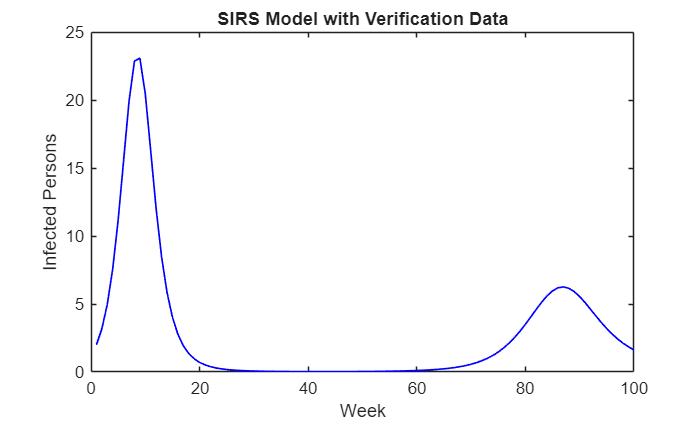

function [s_n, i_n, r_n] = action_sirs(s, i, r, beta, gamma, alpha)
% Advance an SIRS model one timestep

% compute new infections and recoveries
infected = beta * i * s;
recovered = gamma * i;
resuseptible = alpha * r;

infected = min(infected, s);
recovered = min(recovered, i);
resuseptible = min(resuseptible, r);

% Update state
s_n = s - infected + resuseptible;
i_n = i + infected - recovered;
r_n = r + recovered - resuseptible;

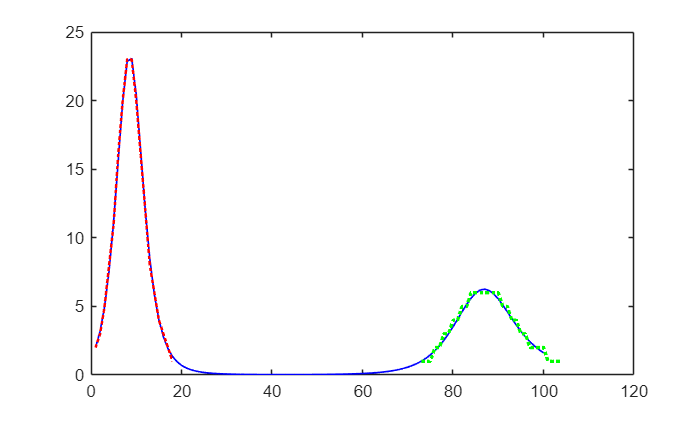


% Enforce invariants; necessary since we're doing a discrete approx.
s_n = max(s_n, 0);

i_n = max(i_n, 0);
r_n = max(r_n, 0);
    
end

% Run simulation
[S_long, I_long, R_long, W_long] = simulate_sirs(s_1, i_1, r_1, beta, gamma, alpha, week_end);

% Plot the fitted simulation
figure()
title("SIRS Model")
plot(W_long, I_long, 'b-', 'LineWidth', 1, 'DisplayName', 'Simulated'); hold on
xlabel("Week")
ylabel("Infected Persons")
hold off

This model can be overlaid with a dataset to anecdotally show its accuracy:

% Load the training + validation data
tab_data_validate = readtable("wave1.csv", "Delimiter", ",");
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");

% Plot the model + data
title("SIRS Model with Verification Data")
plot(W_long, I_long, 'b-', 'LineWidth', 1, 'DisplayName', 'Simulated'); hold on
plot(tab_data_validate.Week, tab_data_validate.InfectedCount, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Wave 1')
plot(tab_data_wave2.Week, tab_data_wave2.InfectedCount, 'g:', 'LineWidth', 2.0, 'DisplayName', 'Wave 2')

Noteably this model can show a second wave of infections due to recovered individuals becoming re-susceptible.

## **Implementation of the SIRVD model**

Now for the SIRVD model. Similar to the SIRS model the SIRVD model takes into account people becoming re-susceptible. The main difference is the additional variables for **V**accinations and **D**eaths. By adding these stocks in we are able to see more complex behavior.

This is the code for one step of the SIRVD model:

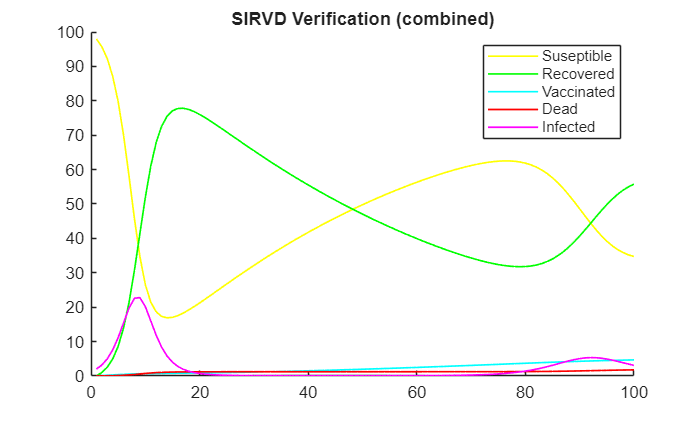

function [s_n, i_n, r_n, v_n, d_n] = action_sirvd(s, i, r, v, d, beta, gamma, alpha, sigma, p)
% Advance an SIRVD model one timestep

% compute new infections and recoveries
infected = beta * i * s;
resuseptible = alpha * r;
vaccinated = sigma * s;
recovered = (1-p) * gamma * i;
dead = p * gamma * i;

infected = min(infected, s);
recovered = min(recovered, i);
resuseptible = min(resuseptible, r);

% Update state
s_n = s - infected + resuseptible - vaccinated;
i_n = i + infected - recovered - dead;
r_n = r + recovered - resuseptible;
v_n = v + vaccinated;
d_n = d + dead;

% Enforce invariants; necessary since we're doing a discrete approx.
s_n = max(s_n, 0);
i_n = max(i_n, 0);
r_n = max(r_n, 0);
    
end

To verify our implementation of the SIRVD model, we tested several values for all of the rate parameters. We chose these values to make a "worst case senario" to stress test the model. Below are some values that created a graph closer to what we expected to see created by our future parameter sweeps.

% Configure the simulation
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
alpha = 1/60;  % Resuseptible rate
sigma = 0.001;     % Vaccination rate
p = 0.013;     % Mortality rate
week_end = 100;

% Initial number of persons in each stock
i_1 = 2;
s_1 = 100 - i_1;
r_1 = 0;
v_1 = 0;
d_1 = 0;

Then we can run the verification simulation

% Run the simulation
[S_sirvd, I_sirvd, R_sirvd, V_sirvd, D_sirvd, W_sirvd] = simulate_sirvd(s_1, i_1, r_1, v_1, d_1, beta, gamma, alpha, sigma, p, week_end);

The next step in verification is checking that the model represents what we would expect from the real world

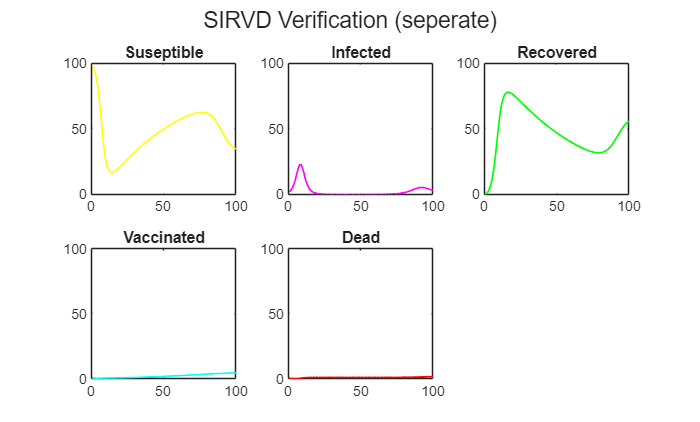

% Add all of the stocks to check the total number of people
T_sirvd = S_sirvd + I_sirvd + R_sirvd + V_sirvd + D_sirvd;

% Assert that the total never exceeds 100 peeople
assert(all(T_sirvd-100 < 1e-10))

% Assert that the number of vaccinated people never goes down
assert(all(diff(V_sirvd)>=0))

% Assert that the number of deceased people never goes down
assert(all(diff(D_sirvd)>=0))


% Assert that no stock goes below zero
assert(all([S_sirvd(:); I_sirvd(:); R_sirvd(:); V_sirvd(:); D_sirvd(:)] >= 0))

% Assert that no stock goes above the population size
assert(all([S_sirvd(:); I_sirvd(:); R_sirvd(:); V_sirvd(:); D_sirvd(:)] <= 100))

To visually see that the stocks were interacting with each other in a resonable manner, we graphed all of the stocks on the same graph, then all of them on their own graph

figure()
hold on
title("SIRVD Verification (combined)")
plot(W_sirvd, S_sirvd, 'y-', 'LineWidth', 1, 'DisplayName', 'Suseptible');
plot(W_sirvd, R_sirvd, 'g-', 'LineWidth', 1, 'DisplayName', 'Recovered');
plot(W_sirvd, V_sirvd, 'c-', 'LineWidth', 1, 'DisplayName', 'Vaccinated');
plot(W_sirvd, D_sirvd, 'r-', 'LineWidth', 1, 'DisplayName', 'Dead');
plot(W_sirvd, I_sirvd, 'm-', 'LineWidth', 1, 'DisplayName', 'Infected');
legend()

figure()
sgtitle("SIRVD Verification (seperate)")
subplot(2, 3, 1)
plot(W_sirvd, S_sirvd, 'y-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRVD'); hold on
ylim([0 100])
title('Suseptible')

subplot(2, 3, 2)
plot(W_sirvd, I_sirvd, 'm-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRVD'); hold on
ylim([0 100])
title('Infected')

subplot(2, 3, 3)
plot(W_sirvd, R_sirvd, 'g-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRVD'); hold on
ylim([0 100])
title('Recovered')

subplot(2, 3, 4)
plot(W_sirvd, V_sirvd, 'c-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRVD'); hold on
ylim([0 100])
title('Vaccinated')


subplot(2, 3, 5)
plot(W_sirvd, D_sirvd, 'r-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRVD'); hold on
ylim([0 100])
title('Dead')

# **Results:**

We decided to sweep over both vaccination rate and mortality rate, one at a time. To find the range to sweep over, we started with zero for both and swept up to a value just beyond where the second wave all but dissapears. This ensures the domain of the graph captures all of the important data to answer our question, "How do the factors of vaccination and death effect a disease?"

The metric we used to record the result of the sweeps were the maximum number of people infected during wave 1 and wave 2. To find this, we used the *islocalmax* function in matlab.

We chose to end the simulation at week 300 instead of week 100 because an increasing mortality rate had the tendency to shift the second wave beyond the scope of a 100-week simulation.

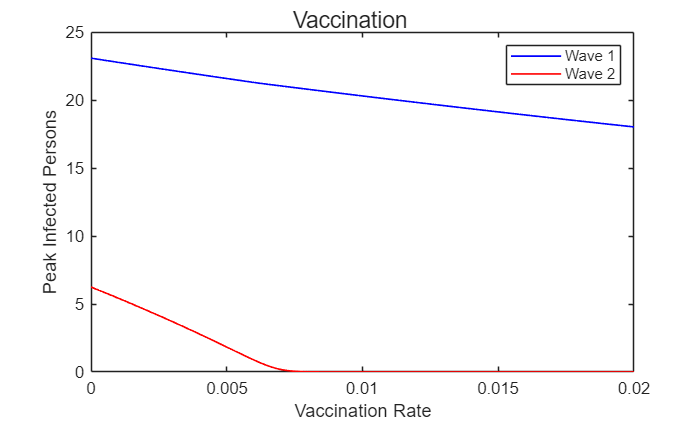

% Vaccination rates to sweep over
sigma_all = linspace(0, 1/50, 200);

% Mortality rates to sweep over
p_all = linspace(0, 0.5, 200);

% Metrics
wave1_maxes_v = zeros(1, length(sigma_all));
wave2_maxes_v = zeros(1, length(sigma_all));

wave1_maxes_d = zeros(1, length(p_all));
wave2_maxes_d = zeros(1, length(p_all));

% Configure the simulation
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
alpha = 1/60;  % Resuseptible Rate
sigma = 0;     % Default vaccinaton rate
p = 0;         % Default mortality Rate
week_end = 300;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;
v_1 = 0;
d_1 = 0;


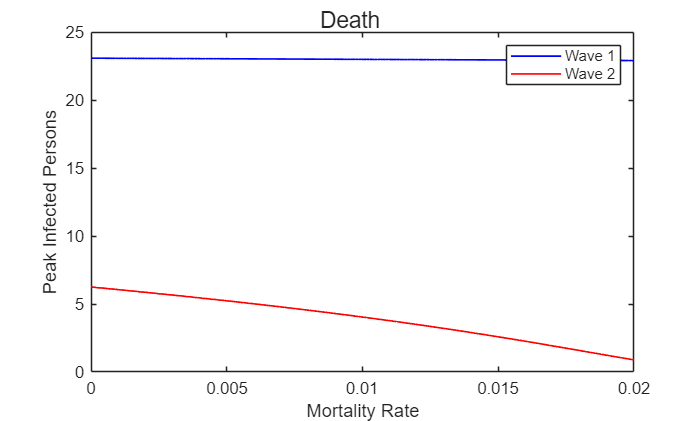

function [I_max_wave1, I_max_wave2] = wave_maxes(I_sirvd, W_sirvd)
    % Isolate the two maxima
    idx = islocalmax(I_sirvd);
    
    W_max = zeros(1, 2);
    I_max = zeros(1, 2);
    
    W_max = W_sirvd(idx);
    I_max = I_sirvd(idx);
    
    I_max_wave1 = I_max(1);

    
    if numel(I_max) >= 2
        I_max_wave2 = I_max(2);
    else
        I_max_wave2 = 0;
    end
end

% Sweep over vaccination rate
for i = 1:length(sigma_all)
    sigma_temp = sigma_all(i);
    [S_sirvd, I_sirvd, R_sirvd, V_sirvd, D_sirvd, W_sirvd] = simulate_sirvd(s_1, i_1, r_1, v_1, d_1, beta, gamma, alpha, sigma_temp, p, week_end);
    [wave1_maxes_v(i), wave2_maxes_v(i)] = wave_maxes(I_sirvd, W_sirvd);
end

% Sweep over mortality rate
for i = 1:length(p_all)
    p_temp = p_all(i);
    [S_sirvd, I_sirvd, R_sirvd, V_sirvd, D_sirvd, W_sirvd] = simulate_sirvd(s_1, i_1, r_1, v_1, d_1, beta, gamma, alpha, sigma, p_temp, week_end);
    [wave1_maxes_d(i), wave2_maxes_d(i)] = wave_maxes(I_sirvd, W_sirvd);
end

**Result Graphs**

figure()
sgtitle("Vaccination")
plot(sigma_all, wave1_maxes_v, 'b-', 'LineWidth', 1, 'DisplayName', 'Wave 1'); hold on
plot(sigma_all, wave2_maxes_v, 'r-', 'LineWidth', 1, 'DisplayName', 'Wave 2');
legend()

yl = ylim;
ylim([0, yl(2)])

xlabel("Vaccination Rate")
ylabel("Peak Infected Persons")
figure()
sgtitle("Death")
plot(sigma_all, wave1_maxes_d, 'b-', 'LineWidth', 1, 'DisplayName', 'Wave 1'); hold on
plot(sigma_all, wave2_maxes_d, 'r-', 'LineWidth', 1, 'DisplayName', 'Wave 2');
legend()

yl = ylim;
ylim([0, yl(2)])

xlabel("Mortality Rate")
ylabel("Peak Infected Persons")

## Analysis

**Vaccination**

The trend in the first wave infected people was that even a large increase in vaccination could not produce a large decrease in peak infected people. However, even a tiny change in vaccination (0.007) was able to entirely remove the second wave and prevent further sickness.

**Mortality**

An increasing mortality rate had no effect on wave 1 peak infections. This is because deaths only decrease the number of infections by preventing people from going from recovered back to suseptible. Therefore, the only way death could have an effect on the first peak is if it happened over a very large period of time. However, death *did* have a large impact on the second wave. While it didn't shrink the peak infections significantly, it shifted the second wave back enormously. Even a relatively small death rate of 0.013 shifted the second wave beyond week 150. As such, we had to exand the time frame of the simulation to accomodate for the late-acting second wave.

# **Interpretation:**

The results effectively show the impacts of vaccination and mortality. For vaccinations we found that even very small vaccination rates (>0.0075 in our case) were enough to prevent a second wave of infections. Mortality rate had a more linear impact on second wave infections with little to no impact on first wave infections.

Further steps that could be taken in this project include:

- Implementing a more accurate vaccination model that takes into account vaccines variability in effectiveness.

- Validate the model with real world data.

Implementing these changes may allow the model to answer questions about real world diseases. It would be really interesting to see what the minimum vaccination rate needs to be to reduce second wave disease spread in actual diseases. Fortunately it would not require a complete re-write of the simulation but there would have to be changes to the equations used for each step. This exercise is left to the reader...